Load and set up the data

basedir = '/Users/yoni/Dropbox/empathy for pain/analyses';
cd(basedir);

mcal = readtable('mcallaster_stim_data.xlsx');

mcal.gender_code = grp2idx(categorical(mcal.gender))

mcal =        videoClips       targetID    gender    AFF_0_16_    OPR_0_5_    SEN_0_16_    VAS_0_10_    PSPI_peak    gender_code
    ________________    ________    ______    _________    ________    _________    _________    _________    ___________

    'll042t1aaaff'       42         'Fe'       7           3           10            6            6           1          
    'll042t1aaunaff'     42         'Fe'       1           0            2            1            0           1          
    'll042t1aeunaff'     42         'Fe'       2           0            2            2            0           1          
    'll042t1afaff'       42         'Fe'       5           3            8   

% 1 = female, 2 = male

%% break up data, placing each subject in one cell
subj_ids = unique(mcal.targetID);

[observed_pain, self_reported_pain, facial_pain] = deal({});
gender = [];

for i=1:length(subj_ids)
    subj_inds = mcal.targetID == subj_ids(i);
    
    observed_pain{i} = mcal.OPR_0_5_(subj_inds);
    self_reported_pain{i} = mcal.VAS_0_10_(subj_inds);
    facial_pain{i} = mcal.PSPI_peak(subj_inds);
    self_and_facial{i} = [mcal.VAS_0_10_(subj_inds) mcal.PSPI_peak(subj_inds)];
    
    a = find(subj_inds);
    gender(i) = mcal.gender_code(a(1));
end

fprintf('We have %d targets, of whom %d are female\n', length(subj_ids), sum(gender==1));

We have 25 targets, of whom 13 are female



gender = zscore(gender);

## Theoretical standpoint

X -> M -> Y

pain experience (self report) --> facial expression --> observer rating

Are any of these paths moderated by gender, controlling for self-reported pain?

Analyses below use only the data already provided by the McAllister database, not with any of the data we collected.  They provided observed pain ratings (though only from one observer) for all stimuli (video clips).  Each "target" (i.e., person w/ shoulder pain) was featured in several video clips.  At the first level, videos-within-target are a random effect.  At the 2nd level, the target's gender is the random effect.  We can also use the observed pain ratings data we collected and model observer as a random effect with a mixed effects model, though we only have data for a subset of the stimuli. I haven't done this yet.

## **PATH A:  Do women and men differently facial express the same amount of self-reported pain?  **(i.e., do women "exagerrate" / do men "suppress" ?).  

Conduct ml glm testing effect of self-reported pain on facial expression of pain, w/ 2nd level for gender.  Test for difference in slope or intercept

glmfit_multilevel(facial_pain, self_reported_pain, gender', 'names', {'L1-Intcpt' 'self-report'},'beta_names', {'L2-Intcpt', 'gender'}, 'noplots');

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  24, Predictors:   2
Outcome names: L1-Intcpt	self-report	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.06 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	L1-Intcpt	self-report	
Adj. mean	-0.81	0.74	

L2-Intcpt
	L1-Intcpt	self-report	
Coeff	-0.81	0.74	
STE	0.76	0.17	
t	-1.06	4.31	
Z	-0.52	3.45	
p	0.3001	0.0003	


gender
	L1-Intcpt	self-report	
Coeff	-0.84	0.06	
STE	0.78	0.18	
t	-1.09	0.32	
Z	-0.56	0.68	
p	0.2889	0.7513	

________________________________________


**There is a numerical effect of men overall facially expressing less pain controlling for self-reported pain, but n.s. (intercept p = .29)**

## **PATH B (but not controlling for X):  for similar facial expressions of pain, are women and men perceived to be in different levels of pain?**  

glmfit_multilevel(observed_pain, facial_pain, gender', 'names', {'L1-Intcpt' 'facial-pain'},'beta_names', {'L2-Intcpt', 'gender'}, 'noplots');

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  24, Predictors:   2
Outcome names: L1-Intcpt	facial-pain	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.05 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	L1-Intcpt	facial-pain	
Adj. mean	0.55	0.57	

L2-Intcpt
	L1-Intcpt	facial-pain	
Coeff	0.55	0.57	
STE	0.11	0.06	
t	4.88	10.06	
Z	3.81	5.99	
p	0.0001	0.0000	


gender
	L1-Intcpt	facial-pain	
Coeff	0.08	0.06	
STE	0.12	0.06	
t	0.72	0.97	
Z	0.05	0.41	
p	0.4813	0.3412	

________________________________________


**No sig. moderation by gender.**

## **PATH C (total effect):  Are women and men perceived to be in the same amount of pain when matched on self-reported pain? In other words, d**oes target gender moderate the relationship between reported and observed pain?

glmfit_multilevel(observed_pain, self_reported_pain, gender', 'names', {'L1-Intcpt' 'self-report'},'beta_names', {'L2-Intcpt', 'gender'}, 'noplots');

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  24, Predictors:   2
Outcome names: L1-Intcpt	self-report	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.05 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	L1-Intcpt	self-report	
Adj. mean	-0.08	0.50	

L2-Intcpt
	L1-Intcpt	self-report	
Coeff	-0.08	0.50	
STE	0.21	0.05	
t	-0.41	9.68	
Z	-0.49	5.87	
p	0.6869	0.0000	


gender
	L1-Intcpt	self-report	
Coeff	-0.36	0.07	
STE	0.21	0.05	
t	-1.69	1.41	
Z	-1.25	0.94	
p	0.1047	0.1726	

________________________________________


**A trend toward a gender bias — women are perceived to be in more pain, controlling for self-reported pain (p = .1)**

## PATH B (M->Y controlling for X) and something similar to PATH C':  When you add facial pain to the model, does the effect go away that? (ml-glm)

wh = true(1,25); wh(15) = 0; % drop subj w/ no PSPI variability
glmfit_multilevel(observed_pain(wh), self_and_facial(wh), gender(wh)', 'names', {'L1-Intcpt' 'self-report' 'facial pain'},'beta_names', {'L2-Intcpt', 'gender'}, 'noplots');

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  21, Predictors:   2
Outcome names: L1-Intcpt	self-report	facial pain	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.01 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	L1-Intcpt	self-report	facial pain	
Adj. mean	-0.16	0.35	0.36	

L2-Intcpt
	L1-Intcpt	self-report	facial pain	
Coeff	-0.16	0.35	0.36	
STE	0.27	0.10	0.07	
t	-0.59	3.38	5.43	
Z	-0.15	2.73	4.01	
p	0.5606	0.0031	0.0000	


gender
	L1-Intcpt	self-report	facial pain	
Coeff	0.27	-0.08	0.00	
STE	0.28	0.11	0.07	
t	0.96	-0.72	0.07	
Z	0.39	-0.05	1.58	
p	0.3480	0.4793	0.9433	

________________________________________


**yes it does.  the statistical trend observed above (that women are perceived to be in more pain than men) is n.s. when controlling for facial expression of pain.**

## Test mediation models

*First test without accounting for gender*

X -> M -> Y

self report --> face --> observer rating

No second-level covariates; omitting 2nd level scatterplots.
Cannot find ebayes_bstar field in stats output, so cannot create cov(a,b) scatterplot


Error in mediation_path_diagram


Column   1:	Column   2:	Column   3:	Column   4:	Column   5:	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
      Name       Mean_Value    Std_Error      T           P         Cohens_d
    _________    __________    _________    ______    __________    ________

    'Col   1'     0.7765       0.095024     8.1716     1.221e-07     1.8272 
    'Col   2'    0.33349       0.062018     5.3773    3.4466e-05     1.2024 
    'Col   3'    0.28212       0.077813     3.6256     0.0018005     0.8107 
    'Col   4'     0.5122       0.053811     9.5185    1.1583e-08     2.1284 
    'Col   5'    0.23008       0.054336     4.2344    0.00044867    0.94685 



ans =     1.1635    0.1614    0.4471    0.6349    0.1877
    0.6391    0.4446    0.0739    0.3580    0.2841
    0.3427    0.6801    0.1970    0.4301    0.2330
    0.5000   -0.0000    1.1538    1.1538   -0.0000
    1.2065    0.5918    0.2208    0.9348    0.7140
    1.2272    0.6682   -0.3367    0.4833    0.8200
    0.9581    0.3421    0.2710    0.5988    0.3278
    0.2349    0.7776    0.1426    0.3253    0.1827
    0.6667    0.2500    0.2083    0.3750    0.1667
    0.4418    0.1038    0.3544    0.4002    0.0458


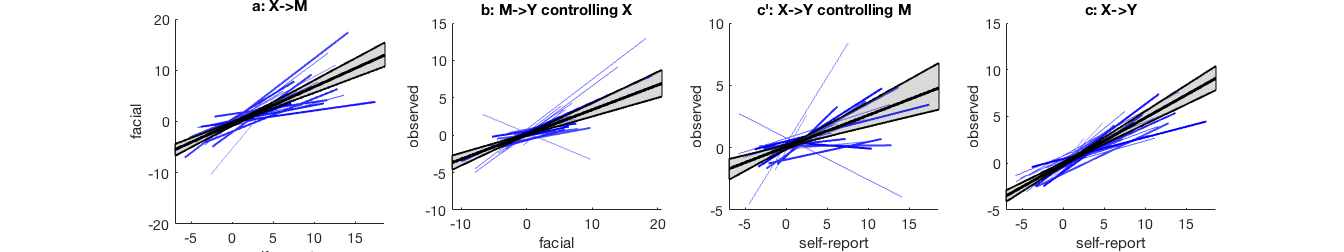

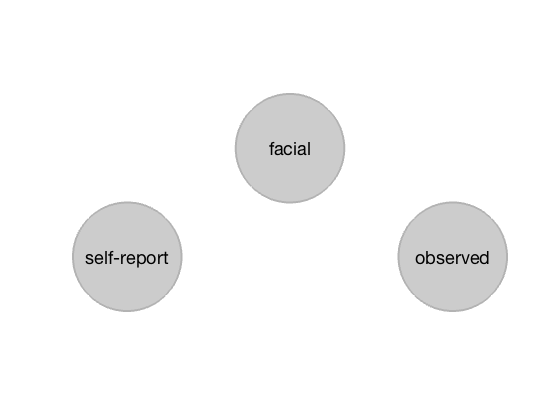

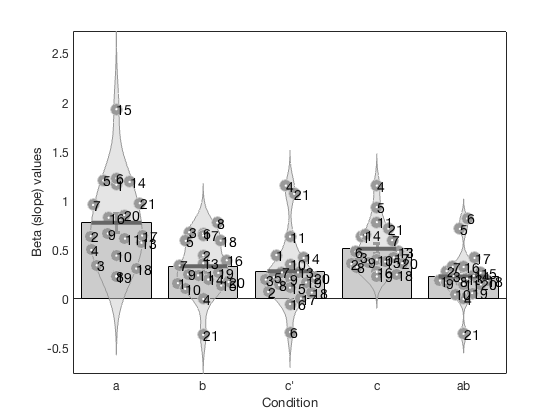

wh = true(25,1);
wh([ 5 7 12  23 ]) = 0; % 7,12, 13 crash code.  5 is an outlier on path a
mediation(self_reported_pain(wh), observed_pain(wh), facial_pain(wh), 'plots', 'names', {'self-report', 'observed', 'facial'})

**Yes, we have significant partial mediation (tho had to drop 4 Ss).  There is both a direct effect of self-report on observed pain and an indirect effect through facial pain, ps < .001.**

## Mediation with gender as L2 moderator

note: the moderation of path a is n.s. in ml-glm conducted above (p = .29), but w/ bootstrapping may be sig?

warning off
mediation(self_reported_pain(wh), observed_pain(wh), facial_pain(wh), 'names', {'self-report', 'observed', 'facial'}, 'L2M', gender(wh)', 'verbose', 'bootstrapfirst')

Mediation analysis

Observations:   1, Replications:  21
Predictor (X): self-report, Outcome (Y): observed: Mediator (M): facial

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: Yes

Getting estimates for replications: 000001
Bootstrapping: 

 Min p-value is 0.050000. Adding   0 samples
 Done in   1 (s) 
002
Bootstrapping: 

 Min p-value is 0.122000. Adding   0 samples
 Done in   0 (s) 
003
Bootstrapping: 

 Min p-value is 0.138000. Adding   0 samples
 Done in   0 (s) 
004
Bootstrapping: 

 Min p-value is 0.168000. Adding   0 samples
 Done in   1 (s) 
005
Bootstrapping: 

 Min p-value is 0.006000. Adding 3881 samples
  Adding 3881 samples 

 Done adding in   1 s 
Done in   1 (s) 
006
Bootstrapping: 

 Min p-value is 0.002000. Adding 4867 samples
  Adding 4867 samples 

 Done adding in   1 s 
Done in   1 (s) 
007
Bootstrapping: 

 Min p-value is 0.006000. Adding 3881 samples
  Adding 3881 samples 

 Done adding in   1 s 
Done in   1 (s) 
008
Bootstrapping: 

 Min p-value is 0.182000. Adding   0 samples
 Done in   0 (s) 
009
Bootstrapping: 

 Min p-value is 0.001000. Adding 4867 samples
  Adding 4867 samples 

 Done adding in   1 s 


Done in   2 (s) 
010
Bootstrapping: 

 Min p-value is 0.076000. Adding   0 samples
 Done in   0 (s) 
011
Bootstrapping: 

 Min p-value is 0.001000. Adding 4867 samples
  Adding 4867 samples 

 Done adding in   1 s 
Done in   1 (s) 
012


013
Bootstrapping:  Min p-value is 0.001000. Adding 4867 samples
  Adding 4867 samples 

 Done adding in   1 s 
Done in   1 (s) 
014
Bootstrapping: 

 Min p-value is 0.012000. Adding 1417 samples
  Adding 1417 samples 

 Done adding in   0 s 
Done in   0 (s) 
015
Bootstrapping: 

 Min p-value is 0.002000. Adding 4867 samples
  Adding 4867 samples 

 Done adding in   1 s 
Done in   1 (s) 
016
Bootstrapping: 

 Min p-value is 0.008000. Adding 2648 samples
  Adding 2648 samples 

 Done adding in   0 s 
Done in   0 (s) 
017
Bootstrapping: 

 Min p-value is 0.028000. Adding  13 samples
  Adding  13 samples 

 Done adding in   0 s 
Done in   0 (s) 
018
Bootstrapping: 

 Min p-value is 0.428000. Adding   0 samples
 Done in   0 (s) 
019
Bootstrapping: 

 Min p-value is 0.006000. Adding 3881 samples
  Adding 3881 samples 

 Done adding in   1 s 
Done in   1 (s) 
020
Bootstrapping: 

 Min p-value is 0.001000. Adding 4867 samples
  Adding 4867 samples 

 Done adding in   3 s 


Done in   3 (s) 
021
Bootstrapping: 

 Min p-value is 0.006000. Adding 3881 samples
  Adding 3881 samples 

 Done adding in   1 s 
Done in   1 (s) 
 Done.



________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	0.68	0.33	0.23	0.48	0.20	
STE	0.08	0.06	0.06	0.05	0.04	
t (~N)	8.30	5.21	3.64	10.41	5.11	
Z	5.12	3.64	3.04	5.72	3.81	
p	0.0000	0.0003	0.0024	0.0000	0.0001	

________________________________________

________________________________________
Second Level Moderator
Multi-level model
	a	b	c'	c	ab	
Coeff	-0.11	0.02	0.01	-0.02	-0.04	
STE	0.08	0.06	0.06	0.05	0.04	
t (~N)	-1.26	0.30	0.21	-0.48	-0.91	
Z	-1.21	0.29	0.20	-0.47	-0.88	
p	0.2247	0.7705	0.8401	0.6407	0.3782	

________________________________________
Total time:  17 s


ans =     1.1635    0.1614    0.4471    0.6349    0.1877
    0.6391    0.4446    0.0739    0.3580    0.2841
    0.3427    0.6801    0.1970    0.4301    0.2330
    0.5000   -0.0000    1.1538    1.1538   -0.0000
    1.2065    0.5918    0.2208    0.9348    0.7140
    1.2272    0.6682   -0.3367    0.4833    0.8200
    0.9581    0.3421    0.2710    0.5988    0.3278
    0.2349    0.7776    0.1426    0.3253    0.1827
    0.6667    0.2500    0.2083    0.3750    0.1667
    0.4418    0.1038    0.3544    0.4002    0.0458


**Gender does not moderate any of the paths of the mediation. BUT, I believe we only tested for sig. different SLOPES between groups (right?), while the effect of interest may be on the intercept.**

## Summary of results

-  Controlling for self-reported pain intensity, women are perceived to be in greater pain (p = .1 for 2nd level intercept in ml-glm).  When controlling for facial expressed pain, this statistical trend becomes entirely n.s..

-  Controlling for self-reported pain intensity, women do not facially express more pain  (p = .29).  Note that effect is in expected direction of women facially expressing more pain, but n.s.

- There is strong support for the general mediational model of self-reported pain -> facial expression -> observed pain

- Gender does not moderate any paths of that mediatin.  BUT, I believe we only tested for sig. different SLOPES between groups (right?), while the effect of interest may be on the intercept.

## Multi-level models -- May 19th 2017

read in and set up the data

data_ml = readtable(fullfile(basedir, 'trial-wise data.csv'));


%data_ml.tarGender( data_ml.tarGender==1 ) = 1;
data_ml.tarGender( data_ml.tarGender==2 ) = -1;

subs = unique(data_ml.x___SubID);
n=length(subs)

n = 49

for i=1:n;
    inds = data_ml.x___SubID==subs(i);
    
    % X
    tarVAS{i} = data_ml.tarVAS(inds); 
    PSPI{i} = data_ml.PSPI(inds);     
    tarGen{i} = data_ml.tarGender(inds);
    
    tarGen_PSPI{i} = [tarGen{i} PSPI{i}];
    tarGen_PSPI_tarVAS{i} = [tarGen{i} PSPI{i} tarVAS{i}];
    
    % Y
    subVAS{i} = data_ml.subVAS(inds);
    
    % gender
    tmp = find(inds);
    subjGen(i) = data_ml.subGender(tmp(1));
end
    
subjGen(subjGen==2) = -1;
subjGen(subjGen==1) = 1;

run a ml glm. Y = observed pain.  X = tarGen, PSPI, maybe tarVAS

-1 = female, 1 = male.

stats = glmfit_multilevel(subVAS, tarGen_PSPI_tarVAS, [], 'names', {'Intcpt', 'targ Gen' 'PSPI' 'tar VAS'});

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  49, Predictors:   1
Outcome names: Intcpt	targ Gen	PSPI	tar VAS	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.05 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	Intcpt	targ Gen	PSPI	tar VAS	
Adj. mean	11.61	0.95	2.50	2.12	

2nd-level B01
	Intcpt	targ Gen	PSPI	tar VAS	
Coeff	11.61	0.95	2.50	2.12	
STE	1.42	0.38	0.14	0.15	
t	8.15	2.46	17.75	14.56	
Z	6.32	2.11	8.13	8.13	
p	0.0000	0.0175	0.0000	0.0000	

________________________________________


females are perceived to be in less pain, controlling for facial expression and for self-report of pain, p = .02.

## does subject gender moderate?

stats = glmfit_multilevel(subVAS, tarGen_PSPI_tarVAS, subjGen', 'names', {'Intcpt', 'targ Gen' 'PSPI' 'tar VAS'});

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  49, Predictors:   2
Outcome names: Intcpt	targ Gen	PSPI	tar VAS	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.02 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	Intcpt	targ Gen	PSPI	tar VAS	
Adj. mean	11.80	0.94	2.49	2.13	

2nd-level B01
	Intcpt	targ Gen	PSPI	tar VAS	
Coeff	11.80	0.94	2.49	2.13	
STE	1.42	0.39	0.14	0.15	
t	8.31	2.40	17.46	14.37	
Z	6.38	2.04	8.13	8.13	
p	0.0000	0.0205	0.0000	0.0000	


2nd-level B02
	Intcpt	targ Gen	PSPI	tar VAS	
Coeff	1.87	-0.10	-0.05	0.04	
STE	1.42	0.39	0.14	0.15	
t	1.32	-0.27	-0.36	0.28	
Z	0.87	-0.80	-0.59	0.78	
p	0.1934	0.7894	0.7218	0.7822	

________________________________________


save('ml-glm results.mat', 'stats');

no evidence for moderation by subject gender.

make plots of gender effect

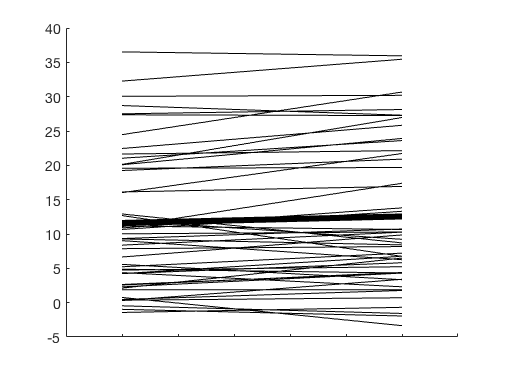

slopes = stats.first_level.beta(2,:)';
intcpt = stats.first_level.beta(1,:)';
X = repmat([0 1], 49, 1);
Y = [intcpt intcpt+slopes];

h=create_figure('slopes of gender effect');
plot(X',Y', 'k');
plot(mean(X)',mean(Y)', 'k', 'LineWidth', 6);
xlim([-.2 1.2])
set(gca, 'XTickLabels', [])

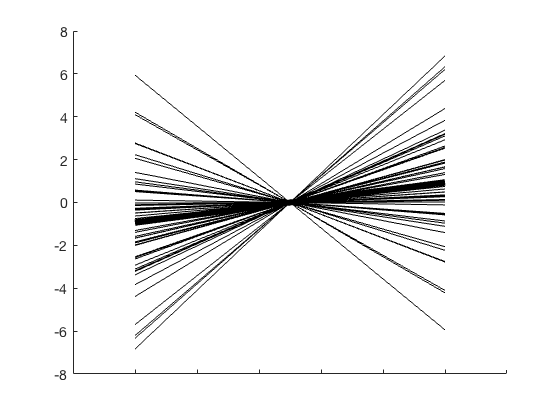


h=create_figure('slopes of gender effect no intcpt');
Y = [-1*slopes slopes];
plot(X',Y', 'k');
plot(mean(X)',mean(Y)', 'k', 'LineWidth', 8);
xlim([-.2 1.2])
set(gca, 'XTickLabels', [])